clear all; close all
A = [ 4 14 -12;
    0 -4 0;
    1.5 -1 -5];
B = [4; 0; 2];
J = [-1 1.2 3.4;
    -0.25 0.9 0.5;
    -0.85 0.8 2.4];
M = [0; 1; 1];
C = [0 1 0];

C = [C; C; C] %making square matrix out of C 

C =      0     1     0
     0     1     0
     0     1     0


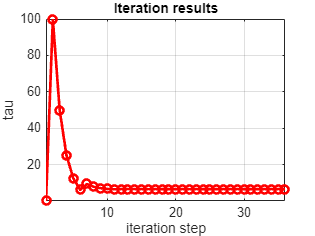



%LMI variables
Pvar = sdpvar(3,3); %Lyapunov matrix
Zvar = sdpvar(3,3); %defining new indepenten matrices
Qvar = sdpvar(3,3);

ii = 100;           % maximal number of iteration steps
jj = 10; %max rough bisection steps

high = 100;
low = 1e-3;
%setting bounds based on expected stability of the solution
lb_tau = 0.01;
ub_tau = 100;
d_tau = 1e-8;

% Set initial loop values
lbf_tau = NaN;
ubf_tau = NaN;

%tracking variables
tau_track = [];
tau_max = 1e4;
for i = 1:ii
    %Computing cvar and dvar using bisection
    tau = bisection(lb_tau,ub_tau,lbf_tau,ubf_tau);
    dvar = 19;
    cvar = -dvar/tau;

    %setting LMI conditions
    [Pvar,Qvar,Zvar, L,diagnostics] = LMI_q2f(A,J,cvar,dvar,Pvar,Qvar,Zvar);

    % Check result
    % pres : Primal constraint residuals
    % dres : Dual constraint residuals
    [pres,~] = check(L);
    [ub_tau, lb_tau, lbf_tau, ubf_tau] = CheckFeasibility(tau,ub_tau,lb_tau,lbf_tau,ubf_tau,pres,diagnostics);

    
    %storing iteration
    tau_track(i) = tau;

    if i>1
         %check has minus two because the variable is changed every other cycle
        if abs(tau-tau_track(i-1)) < d_tau
            break;
        end
        if tau > tau_max
            break;
        end
    end

    % Store feasible solution
    if min(pres) > 0 && diagnostics.problem == 0
        feasible.Pvar = Pvar;
        feasible.Qvar = Qvar;
        feasible.Zvar = Zvar;
        feasible.cvar = cvar;
        feasible.dvar = dvar;
    end

end


% Plot iteration history
figure(1)
plot(tau_track,'ro-','LineWidth',2)
xlabel('iteration step')
ylabel('tau')
title('Iteration results')
grid on
axis tight



% Retrieve output
P = value(feasible.Pvar)

P =     1.6119    2.7705   -3.1401
    2.7705   25.1477   -7.1212
   -3.1401   -7.1212    6.5203



c = value(feasible.cvar)

c = -2.8988

d = value(feasible.dvar)

d = 19



dwelltime = abs(d)/abs(c)

dwelltime = 6.5545